fileS1='02-15-2016_23_06_37_top';

addpath('../Library');
load('BGimg0223');
%Define the physical constant
mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
warning('off','all');
[ KappaTildeT_U, PTildeT_U, TTildeT_U, ~, ~] = VirialUnitarity( );
filefolder_Unitary='/Users/Zhenjie/Data/2016-02-23/';

filefolder_Polarized='/Users/Zhenjie/Data/2016-02-15/';

[~,~,~,VsortS1,~,~,~,EFS1]=EOS_Online( [filefolder_Polarized,fileS1,'.fits'] ,'ROI1',[215,25,312,430],...
    'ROI2',[209,187,335,243],'ShowOutline',0,'TailRange',[60,380],'KappaMode',2,'PolyOrder',10,'VrangeFactor',5,'IfHalf',0,'kmax',0.9,'kmin',0.15,...
    'Fudge',2.62,'BGSubtraction',0,'IfFitExpTail',1,'Nsat',660,'ShowPlot',0);


VsortS1=VsortS1/hh;EFS1=EFS1/hh;

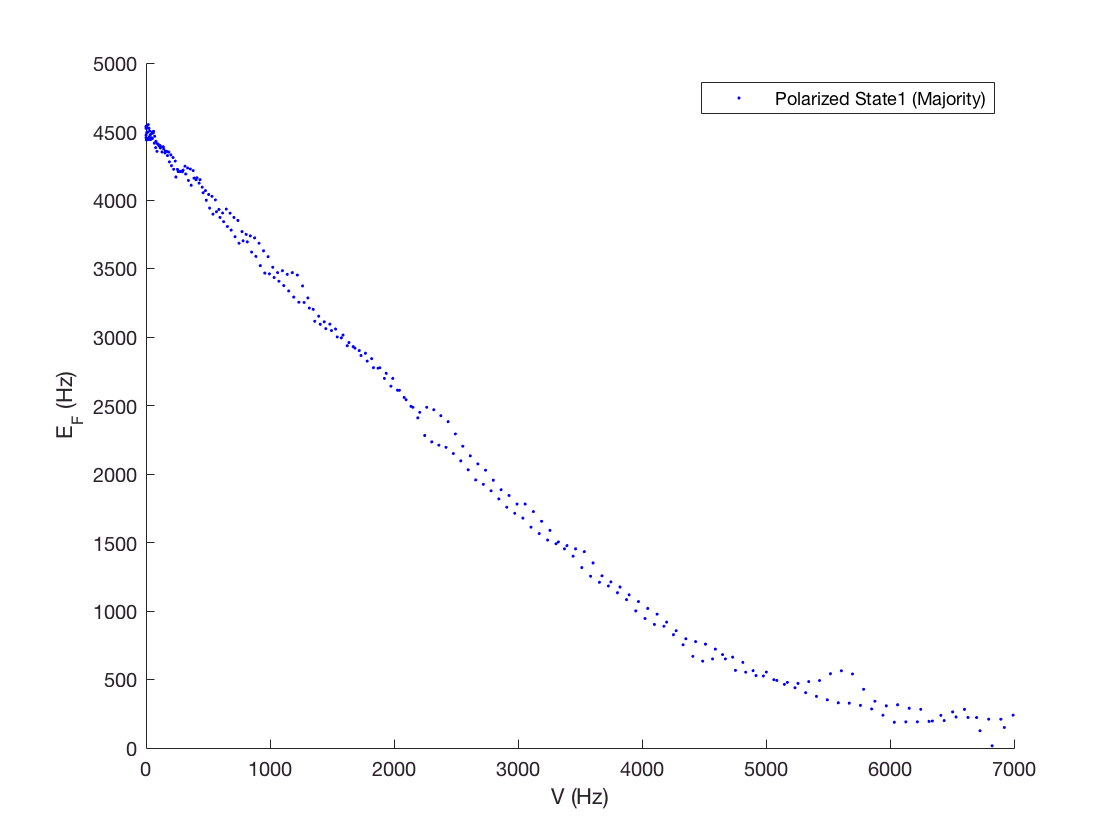

scatter(VsortS1,EFS1,'b.','DisplayName','Polarized State1 (Majority)');
hold on
xlim([0,7000])
legend('Show')
hold off
xlabel('V (Hz)');ylabel('E_F (Hz)');

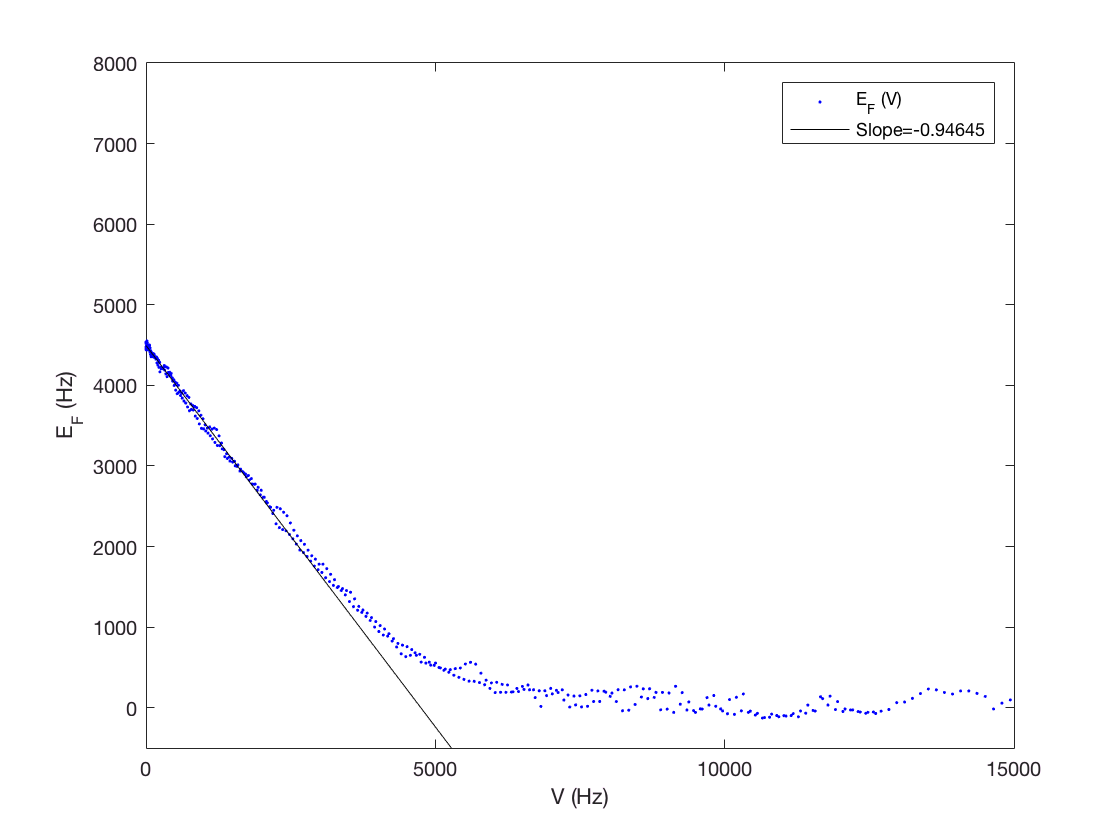

FitRangePolarized1=0;
FitRangePolarized2=2000;
Mark1=(VsortS1<FitRangePolarized2);
Mark2=(VsortS1>FitRangePolarized1);
Mark=Mark1 & Mark2;
EFfitS1=EFS1(Mark);
VfitS1=VsortS1(Mark);

pS1=polyfit(VfitS1,EFfitS1,1);
EFlineS1=polyval(pS1,VsortS1);
plot(VsortS1,EFS1,'b.','DisplayName','E_F (V)');
xlim([0,15000]);ylim([-500,8000]);
hold on
plot(VsortS1,EFlineS1,'k','DisplayName',['Slope=',num2str(pS1(1))]);
xlabel('V (Hz)');ylabel('E_F (Hz)');
legend('show');
hold off

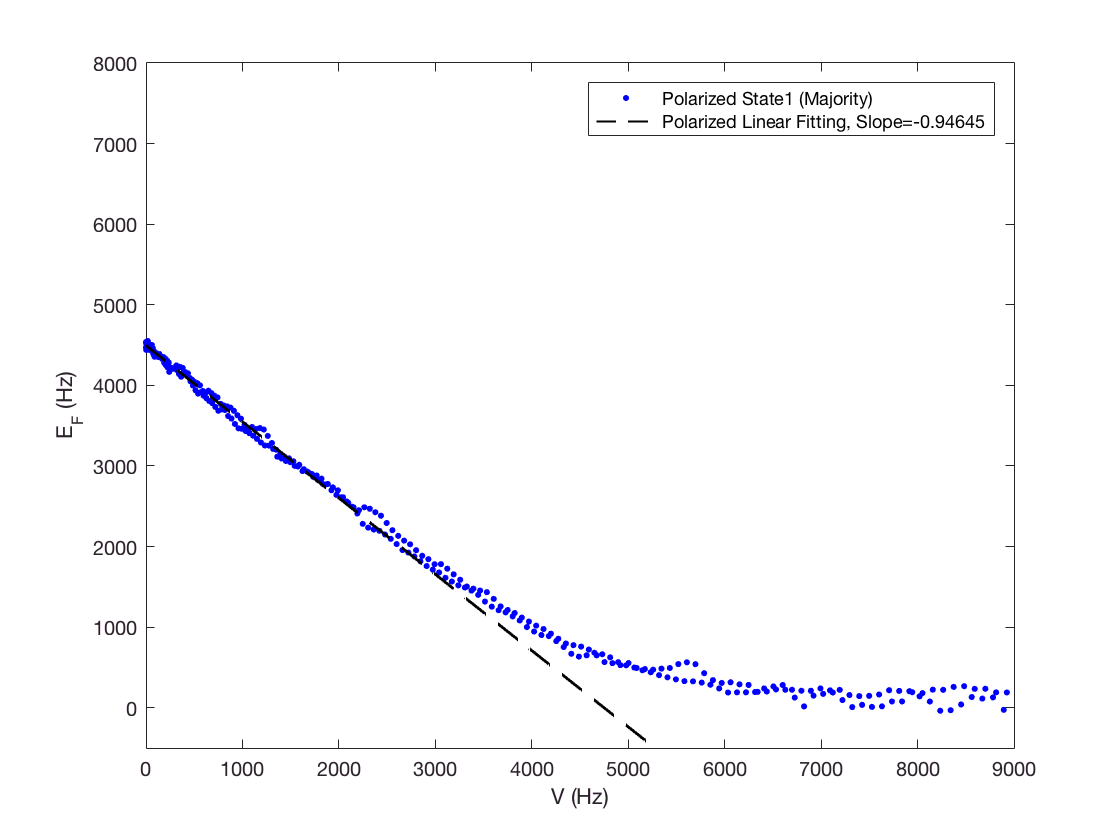

plot(VsortS1,EFS1,'b.','DisplayName','Polarized State1 (Majority)','MarkerSize',15);
hold on
xlim([0,9000]);
plot(VsortS1,EFlineS1,'k--','DisplayName',['Polarized Linear Fitting, Slope=',num2str(pS1(1))],'LineWidth',1);
legend('Show')
ylim([-500,8000]);
hold off
xlabel('V (Hz)');ylabel('E_F (Hz)');

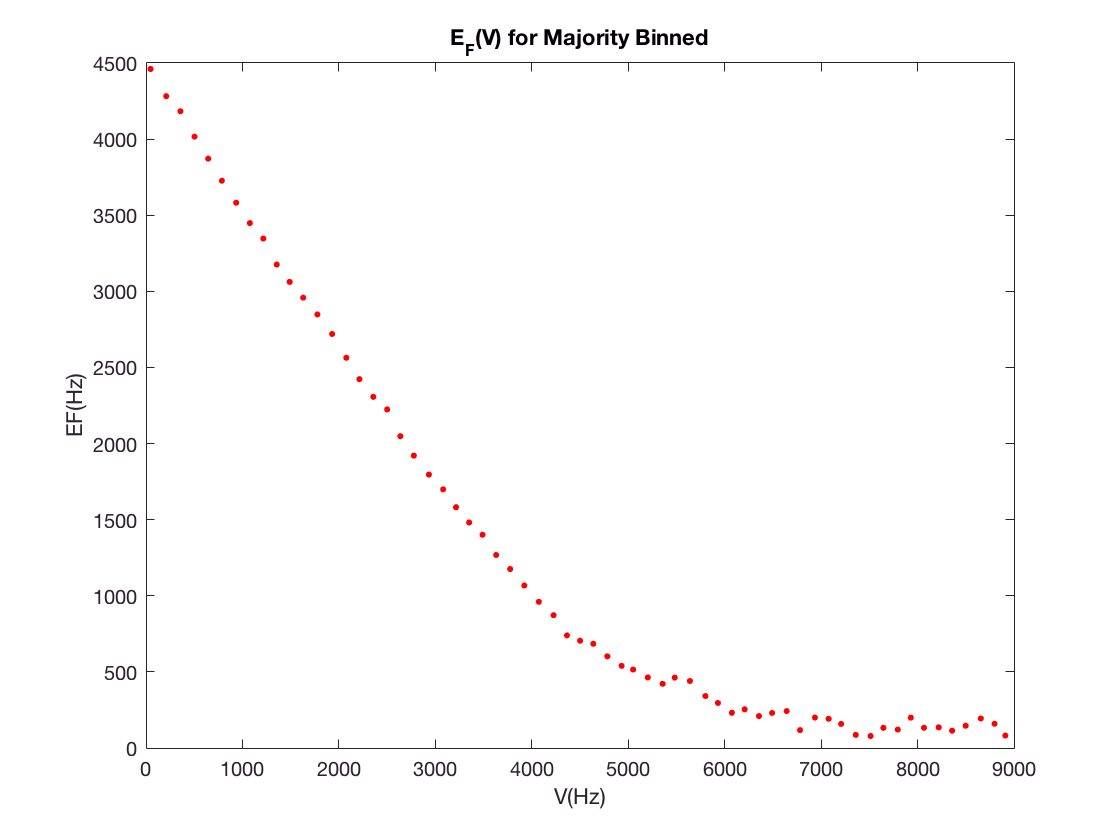

Ngrid=70;
Vgrid=linspace(0,10000,Ngrid+1);
[Vmean,EFS1mean,Verr,EFerr]=BinGrid( VsortS1,EFS1,Vgrid,2);
plot(Vmean,EFS1mean,'r.','MarkerSize',15)
xlabel('V(Hz)');ylabel('EF(Hz)')
title('E_F(V) for Majority Binned');
xlim([0,9000])

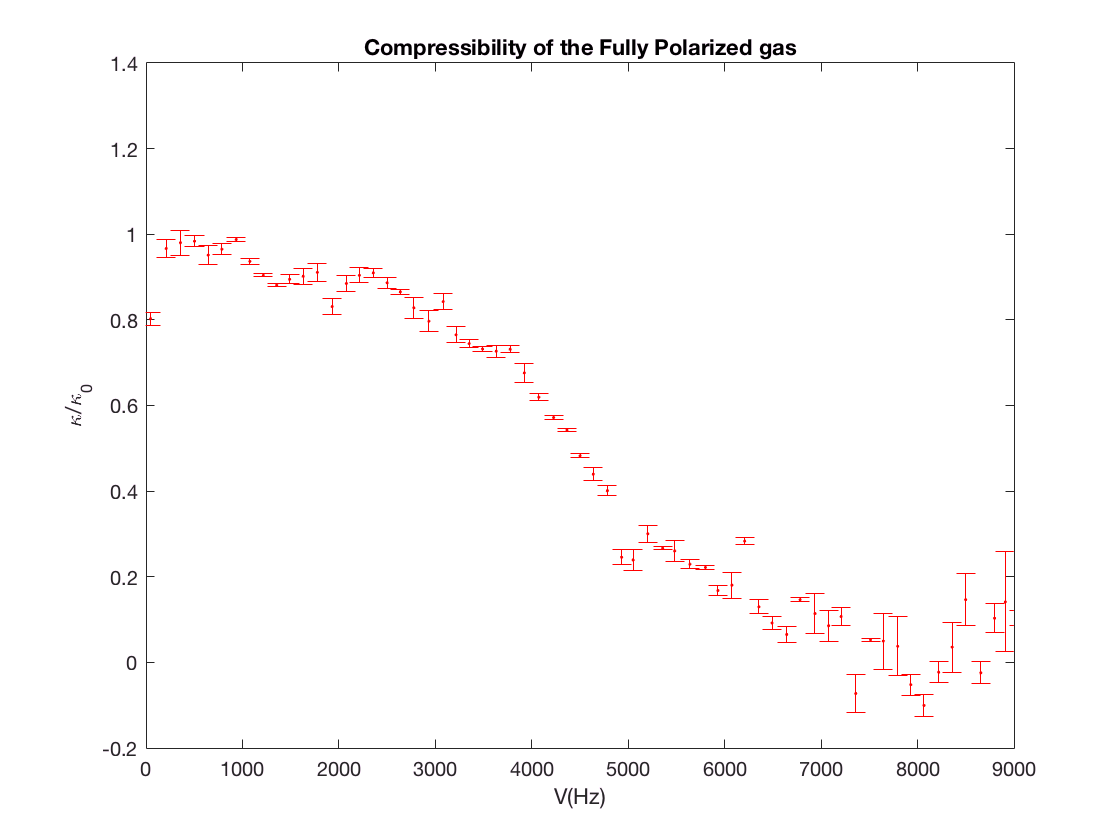


[KappaT,KappaTerr]=FiniteD( Vmean,Verr,EFS1mean,EFerr,4 );
KappaT=-KappaT;
%% Get the Kappa vs V
errorbar(Vmean,KappaT,KappaTerr,'r.')
xlim([0,9000]);ylim([-0.2,1.4])
xlabel('V(Hz)');ylabel('\kappa/\kappa_0')
title('Compressibility of the Fully Polarized gas');